# Costruzione di un segnale ad onda quadra, sua scomposizione e ricomposizione parziale tramite FFT

close all
clear all
clc


## Costruiamo il segnale ad onda quadra

#### <figura che spiega i passaggi>

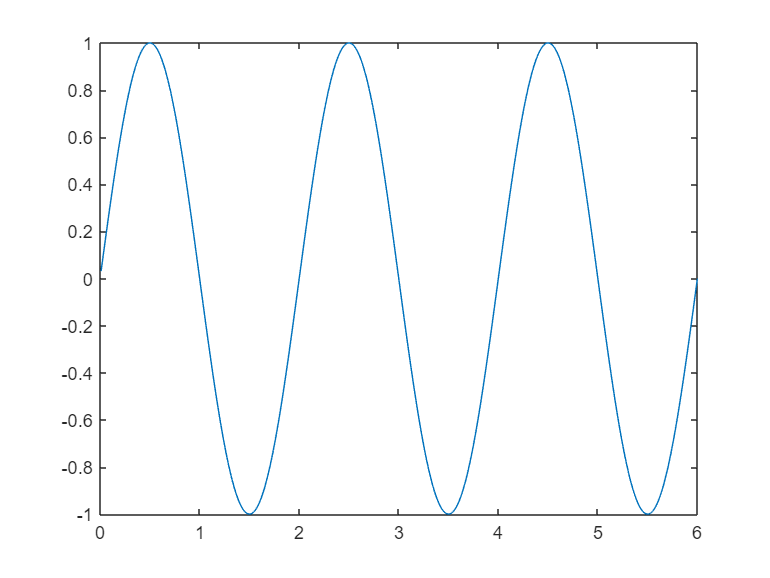

T_finale = 6;
Tc = 0.01;                      % periodo di campionamento
t = Tc:Tc:T_finale;
T0 = 2;        % periodo dell'onda quadra
s = sin(2*pi*t/T0)';            % sinusoide di periodo 'T0'
plot(t,s)

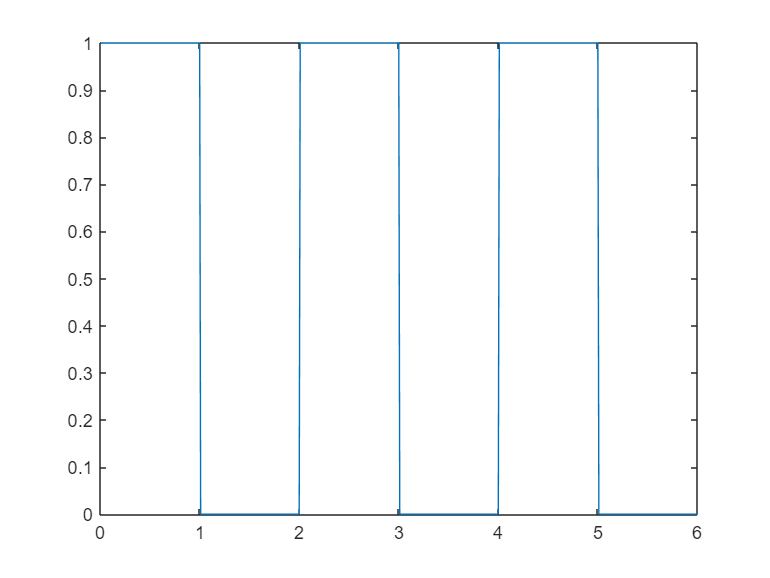


ii = find(s > 0);   % trova gli indici 'ii' per cui il seno è > 0
s = zeros(size(s)); % inizializza un segnale sempre pari a zero
s(ii) = 1;          % solo per gli inidici 'ii' definisce il segnale pari ad 1
plot(t,s)

## Calcoliamo la Trasformata di Fourier tramite FFT

<figura che spiega come si costruisce la base delle frequenze>

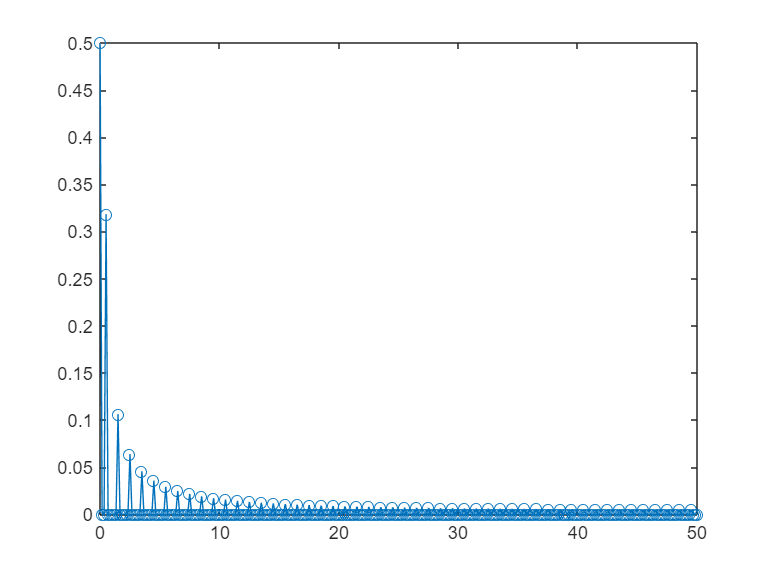

N = length(s);
s_FFT = fft(s)/length(s);   % Fast Fourier Transform di 's'
fN = 1/(2*Tc);              % frequenza di Nyquist
ff = 0:1/T_finale:fN;       % base delle frequenze

% guardiamo solo la parte positiva dello spettro:
plot(ff, abs(s_FFT(1:(N/2+1))), '-o')  

## Ricomponiamo il segnale usando solo alcune delle componenti della FFT

<figura che spiega la ricomposizione parziale>

<Aggiungiamo anche un ritardo temporale>

media = s_FFT(1);               % valore medio
% numero di componenti da usare:
nmax = 96                       

nmax = 96

Ritardo = 0

Ritardo = 0

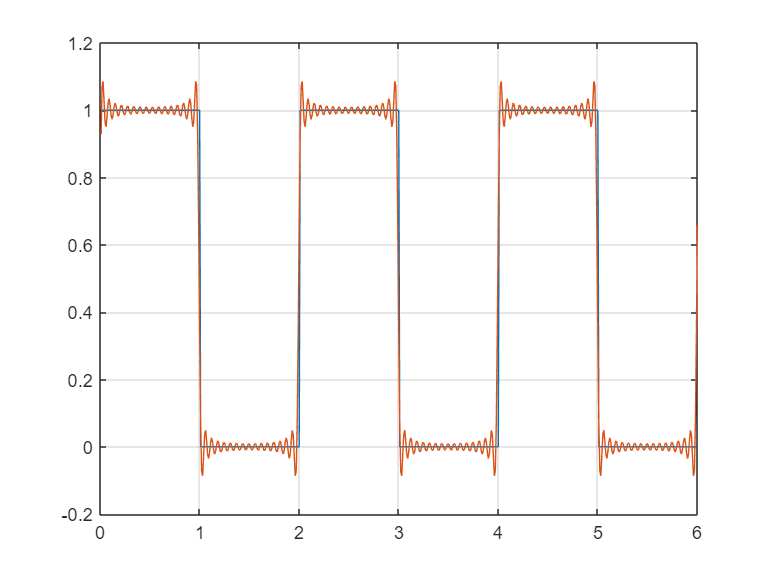

sf = ones(size(t)) * media;
for i = 2:nmax
    sf = sf + 2*abs(s_FFT(i)) * ...
        cos(2 * pi * ff(i) * t + angle(s_FFT(i)) - ...
        2 * pi * ff(i) * Ritardo);
end
    
plot(t,s,t,sf), grid on